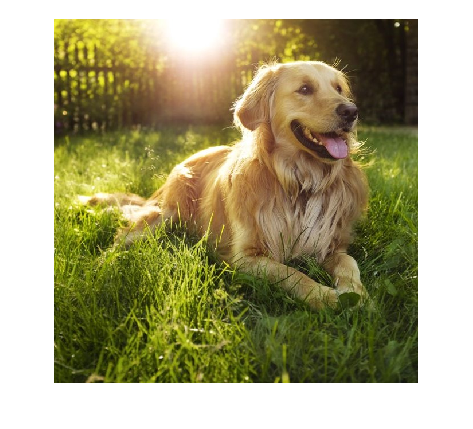

img = imread("squaredog.jpg");
imshow(img);

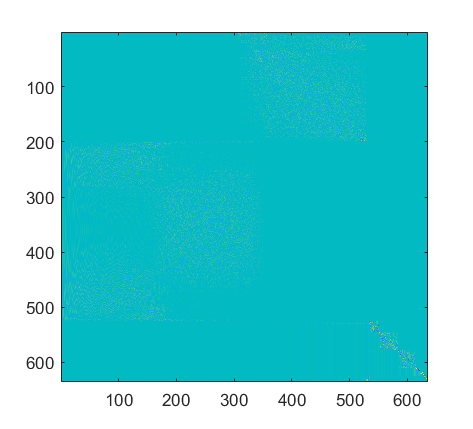


%img = rgb2hsv(img);

R = double(img(:,:,1));
G = double(img(:,:,2));
B = double(img(:,:,3));

[U,T] = schur(R);
%X = zeros(size(U));
%U =  imnoise(U,'salt & pepper',0.01);
%U = medfilt2(U);
%X = [0.5,0;0,0.5];
%U = conv2(U,X,'same');
%U = imgaussfilt(U,0.05);
%T(1:150,300:635) = 0;
%U(1:635,50:635) = 0;

imagesc(U);

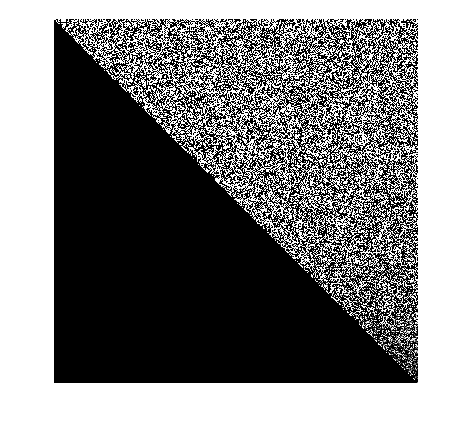

imshow(T);

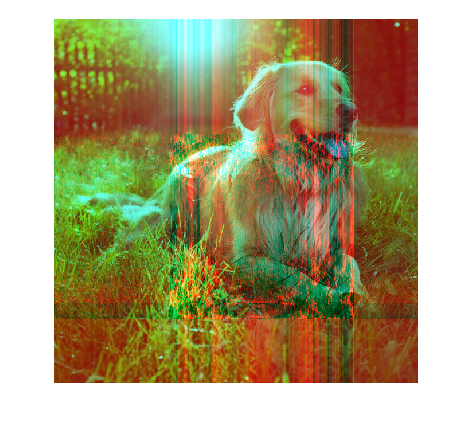


R= X*T*X';
I = uint8((cat(3,R,G,B)));

%imagesc(uint8(R));
imshow(I);